1.4.1

可以发现当n=0,令x3(t)=x1(t)+x2(t)，y3(t)≠x1(t)+x2(t)

x1=1;
x2=1;
y1=1;
y2=0;
x3=x1+x2;
y3=-1;
n=0

n = 0

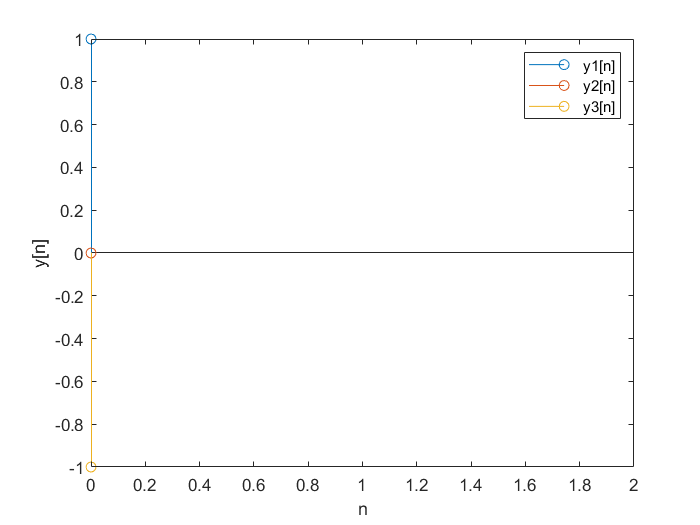

stem(n,y1);
hold on;
stem(n,y2);
hold on;
stem(n,y3);
axis([0 2,-inf,inf]);
hold off;
legend('y1[n]','y2[n]','y3[n]');
xlabel('n');
ylabel('y[n]')

1.4.2 因为y[n]的值取决于未来的输入x[n+1]，所以该信号不是因果的。

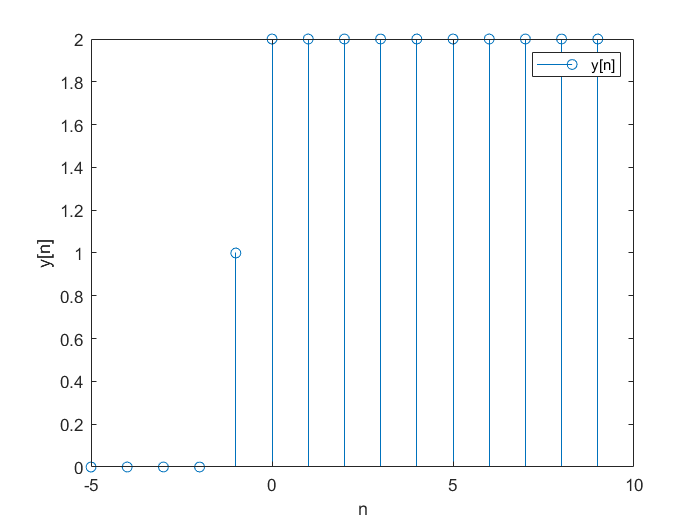

n=-5:9;
x=[0,0,0,0,0,1,1,1,1,1,1,1,1,1,1];
x2=[0,0,0,0,1,1,1,1,1,1,1,1,1,1,1];
y=x+x2;
stem(n,y);
legend('y[n]');
xlabel('n');
ylabel('y[n]')

1.4.3  当n=0时候, y[n]属于无穷小，没有边界，所以该信号不是稳定的。

n=0:0.2:20

n =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000


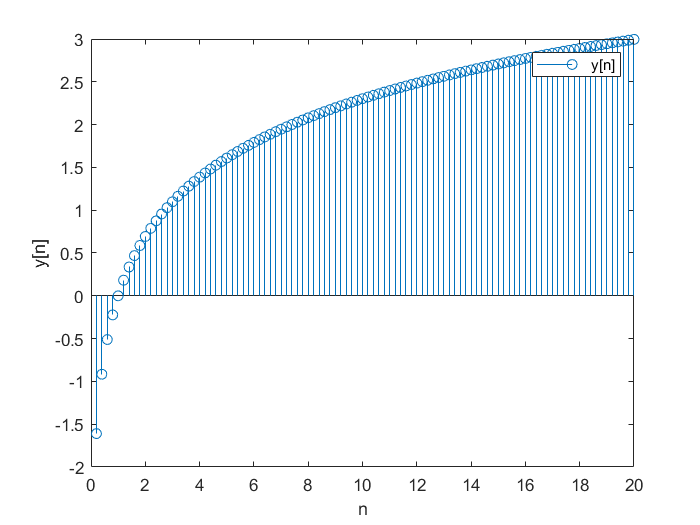

x=0:0.2:20;
y=log(x);
stem(n,y);
legend('y[n]');
xlabel('n');
ylabel('y[n]')

1.4.4令x[n]=n,在[-20,20]范围内,如图所示，可知不同的输入可能导致相同的输入。

x=-20:20;
n=-20:20;
y=sin(pi/2*x)

y =     0.0000    1.0000   -0.0000   -1.0000    0.0000    1.0000   -0.0000   -1.0000    0.0000    1.0000   -0.0000   -1.0000    0.0000    1.0000   -0.0000   -1.0000    0.0000    1.0000   -0.0000   -1.0000         0    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000    1.0000    0.0000   -1.0000   -0.0000


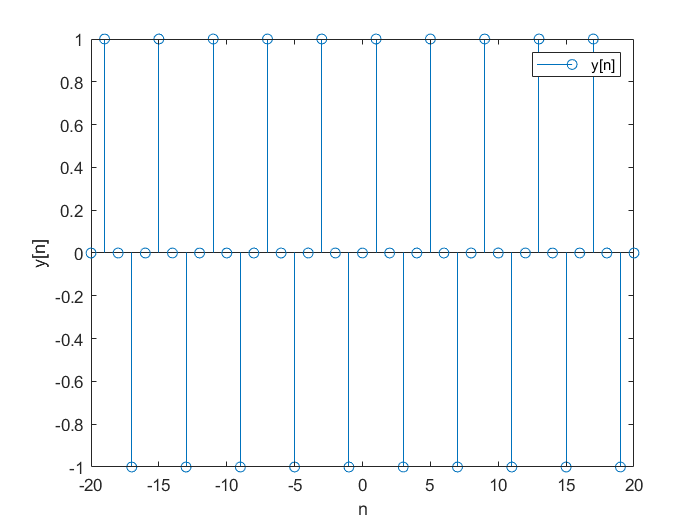

stem(n,y);
legend('y[n]');
xlabel('n');
ylabel('y[n]')

1.4.5    advanced assignment(e)信号不符合线性。

在[-20,20]范围内，令x1[n]=n,x2[n]=n,x3[n]=x1[n]+x2[n];y3[n]=x3[n],可知y1+y2≠y3;

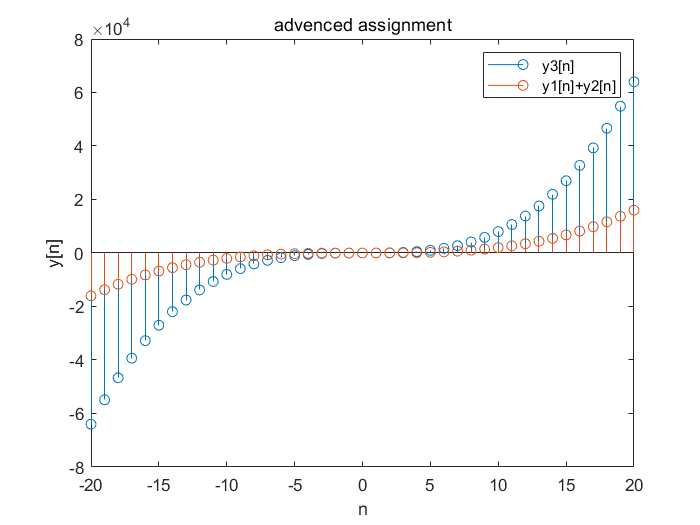

n=-20:20;
x=-20:20;
y1=x.*x.*x;
y2=x.*x.*x;
x3=x+x;
y3=x3.*x3.*x3;

stem(n,y3);
hold on;
stem(n,y1+y2);
hold off;
legend('y3[n]','y1[n]+y2[n]');
xlabel('n');
ylabel('y[n]')
title('advenced assignment')

1.4.6    advanced assignment(f)不符合时不变性、可逆、稳定的

在[-5，5]范围内，令x1[n]=σ[n],则y1[n]恒为0,x2[n]=σ[n-1],y2[n]=σ[n-1],y2[n]不是y1[n]的时移。

令x3[n]=n,则在不同输入下，y[n]可能会有相同的值，所以不符合可逆。

令x4[n]=1,则在不同的输入下，y[n]没有一个确定的上界和下界，所以不是稳定的。

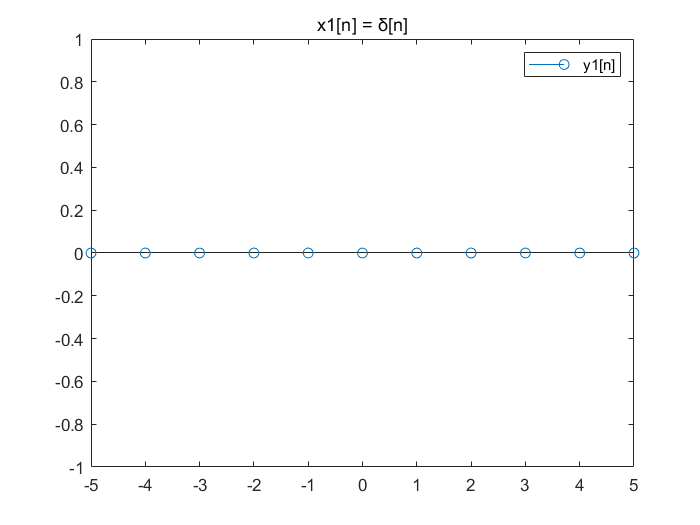

n=-5:5;
x1=[0,0,0,0,0,1,0,0,0,0,0];%x1[n] = δ[n]
x2=[0,0,0,0,0,0,1,0,0,0,0];%x2[n] = δ[n-1]
y1=n.*x1;
y2=n.*x2;
x3=n;
x4=1;
stem(n,y1);
legend('y1[n]');
title('x1[n] = δ[n]')
hold off;

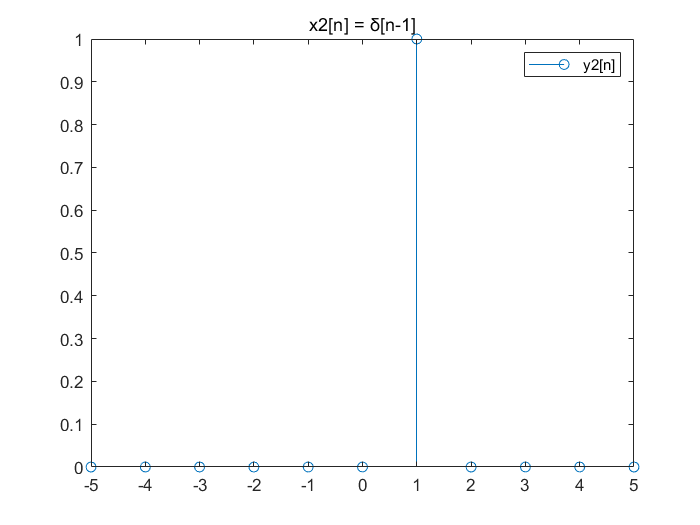

stem(n,y2);
legend('y2[n]');
title('x2[n] = δ[n-1]')
hold off

1.4.6    advanced assignment(g)该系统不符合因果。在n属于[-5，5]范围内,令x[n]=n,y[n]=x[2n]，当n=4时，y[4]=x[8]，输出和未来的值有关

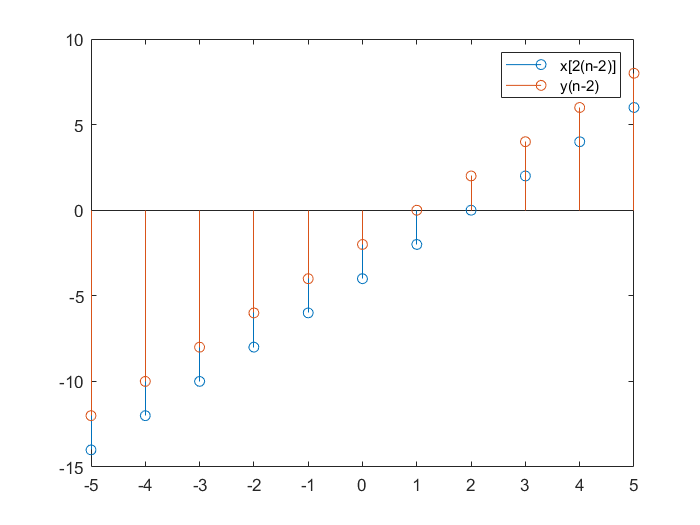

n=-5:5;
x1=n;
x2=n-2;
y1 = 2*n;
y2 = 2*[n-2];%x[2(n-2)]
y3 = 2*n-2;%y[n-2]
stem(n,y2);
hold on;
stem(n,y3);
legend('x[2(n-2)]','y(n-2)');
hold off;

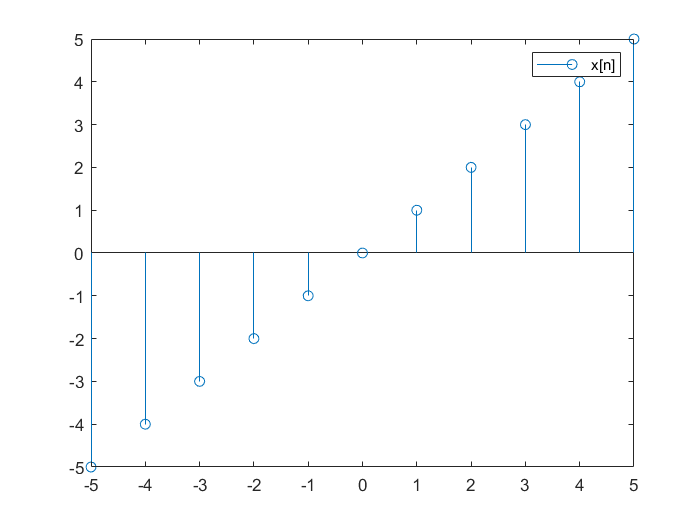

stem (n,x1);
legend('x[n]');

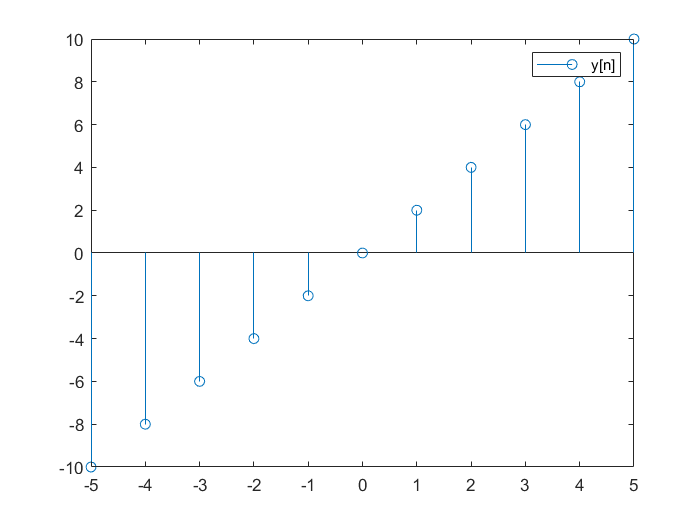

stem(n,y1);
legend('y[n]');